# 3. lab. vježba

#### Određivanje trajektorije i momenta zglobova

1. Zadatak:

zadani podaci:

qi1 = 12.55*pi/180;
qf1 = 16.63*pi/180;
qi2 = 50.55*pi/180;
qf2 = 55.43*pi/180;
qi3 = -3.11*pi/180;
qf3 = -42*pi/180;

tf = 2;
a = 0.1;

4*abs(qf1-qi1)/(tf^2)

ans = 0.0712


0.1 >= q1 %rješenje moguće

ans = logical
   0



tc1 = tf/2-sqrt(tf^2/4-(qf1-qi1)/a)

tc1 = 0.4634

qc1 = a/2*tc1^2+qi1

qc1 = 0.2298

qfc1 = a*tc1*(tf-tc1)+qc1

qfc1 = 0.3010


4*abs(qf2-qi2)/(tf^2)

ans = 0.0852


tc2 = tf/2-sqrt(tf^2/4-(qf2-qi2)/a)

tc2 = 0.6149

qc2 = a/2*tc2^2+qi2

qc2 = 0.9012

qfc2 = a*tc2*(tf-tc2)+qc2

qfc2 = 0.9863


4*abs(qf3-qi3)/(tf^2)

ans = 0.6788


a2 = 1;

tc3 = tf/2-sqrt(tf^2/4-(abs(qf3-qi3))/a2)

tc3 = 0.4332

qc3 = a2/2*tc3^2+qi3

qc3 = 0.0396

qfc3 = a2*tc3*(tf-tc3)+qc3

qfc3 = 0.7183

grafovi i brzine:

syms t

% q1 pozicija
q1=a/2*t^2+qi1

$$q1 = \frac{t^{2}}{20}+\frac{251\,\pi }{3600}$$

fplot(q1,[0,tc1]); hold on;
q1=a*tc1*(t-tc1/2)+qi1

$$q1 = \frac{417422061687361\,t}{9007199254740992}+\frac{251\,\pi }{3600}-\frac{871205887916635060072535721605}{81129638414606681695789005144064}$$

fplot(q1,[tc1,tf-tc1])
qtf1=double(subs(q1,t,tf)); 
q1=qf1-a/2*(tf-t)^2

$$q1 = \frac{1663\,\pi }{18000}-\frac{{\left(t-2\right)}^{2}}{20}$$

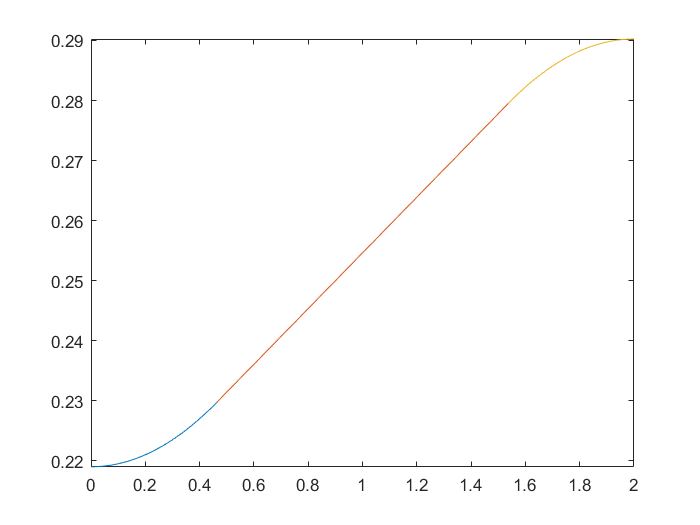

fplot(q1,[tf-tc1 tf])
hold off;


% q1 brzina
om1=a*t

$$om1 = \frac{t}{10}$$

fplot(om1,[0,tc1]); hold on;
om1=a*tc1

om1 = 0.0463

fplot(om1,[tc1,tf-tc1])
om1=a*(tf-t)

$$om1 = \frac{1}{5}-\frac{t}{10}$$

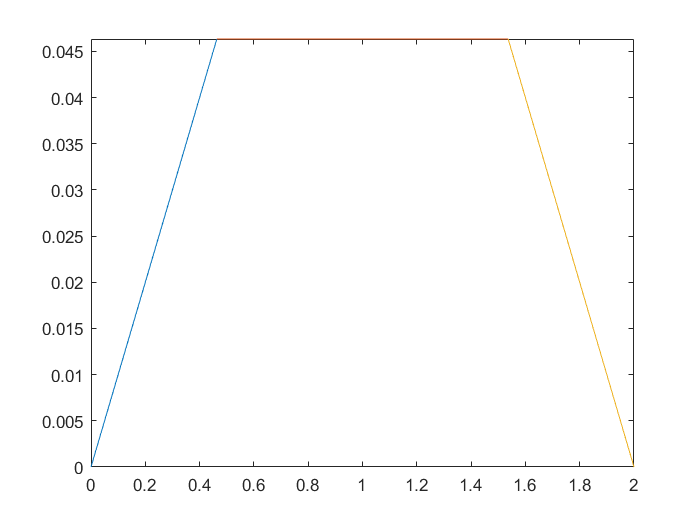

fplot(om1,[tf-tc1 tf])
hold off


% q2 pozicija
q2=a/2*t^2+qi2

$$q2 = \frac{t^{2}}{20}+\frac{337\,\pi }{1200}$$

fplot(q2,[0,tc2]); hold on;
q2=a*tc2*(t-tc2/2)+qi2

$$q2 = \frac{553879212411409\,t}{9007199254740992}+\frac{337\,\pi }{1200}-\frac{1533910909707413648143366826405}{81129638414606681695789005144064}$$

fplot(q2,[tc2,tf-tc2])
qtf2=double(subs(q2,t,tf))

qtf2 = 0.9863

q2=qf2-a/2*(tf-t)^2

$$q2 = \frac{5543\,\pi }{18000}-\frac{{\left(t-2\right)}^{2}}{20}$$

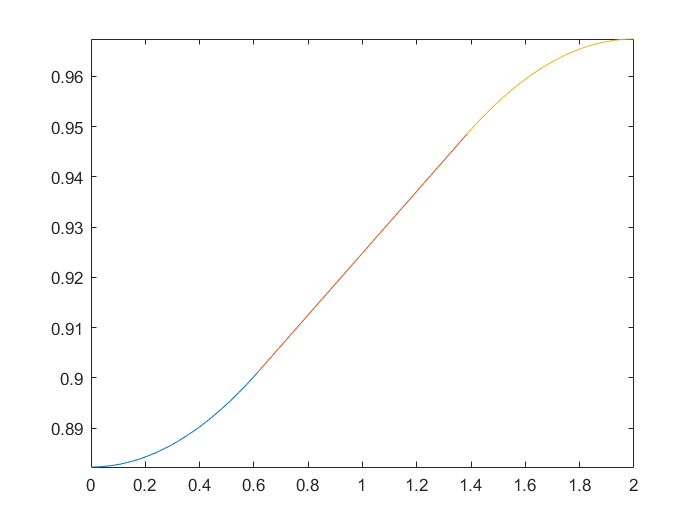

fplot(q2,[tf-tc2 tf])
hold off;


% q2 brzina
om2=a*t

$$om2 = \frac{t}{10}$$

fplot(om2,[0,tc2]); hold on;
om2=a*tc2

om2 = 0.0615

fplot(om2,[tc2,tf-tc2])
om2=a*(tf-t)

$$om2 = \frac{1}{5}-\frac{t}{10}$$

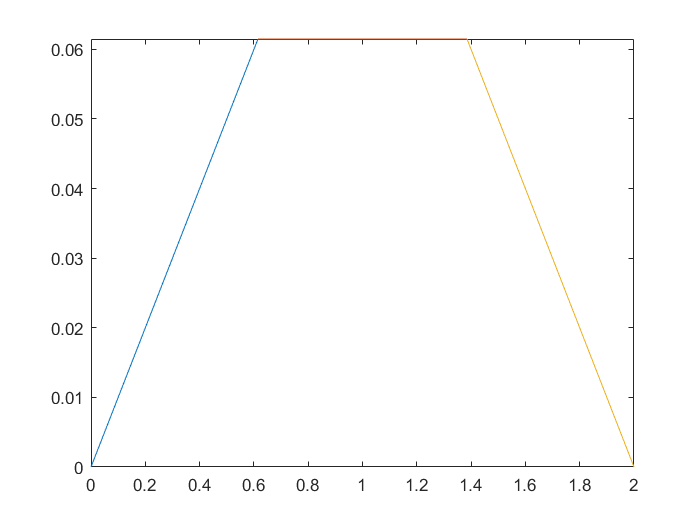

fplot(om2,[tf-tc2 tf])
hold off



% q3 pozicija
q3=-a2/2*t^2+qi3

$$q3 = -\frac{t^{2}}{2}-\frac{311\,\pi }{18000}$$

fplot(q3,[0,tc3]); hold on;
q3=-a2*tc3*(t-tc3/2)+qi3

$$q3 = \frac{15226258599505186842211980095601}{162259276829213363391578010288128}-\frac{311\,\pi }{18000}-\frac{3902083879096551\,t}{9007199254740992}$$

fplot(q3,[tc3,tf-tc3])
qtf3=double(subs(q3,t,tf))

qtf3 = -0.8269

q3=qf3+a2/2*(tf-t)^2

$$q3 = \frac{{\left(t-2\right)}^{2}}{2}-\frac{7\,\pi }{30}$$

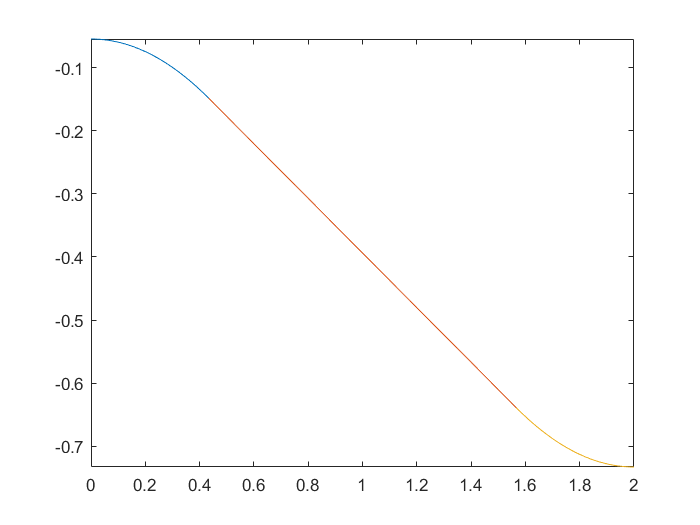

fplot(q3,[tf-tc3 tf])
hold off;


% q3 brzina
om3=a2*t

$$om31 = t$$

fplot(om3,[0,tc3]); hold on;
om3=a2*tc3

om32 = 0.4332

fplot(om3,[tc3,tf-tc3])
om3=a2*(tf-t)

$$om33 = 2-t$$

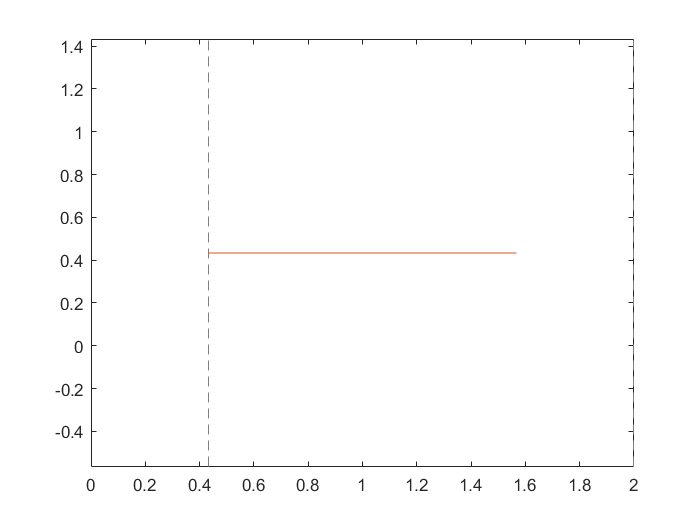

fplot(om3,[tf-tc3 tf])
hold off

2. zadatak:

clear all

syms q1 q2  a1 a2 fx fy   % definiramo simbole

% simboličke funkcije
px=a1*cos(q1)+a2*cos(q1+q2);
py=a1*sin(q1)+a2*sin(q1+q2);


J=jacobian([px, py], [q1, q2]) % jakobijan

$$J = \left(\begin{array}{cc} -a_{2}\,\sin\left(q_{1}+q_{2}\right)-a_{1}\,\sin\left(q_{1}\right) & -a_{2}\,\sin\left(q_{1}+q_{2}\right)\\ a_{2}\,\cos\left(q_{1}+q_{2}\right)+a_{1}\,\cos\left(q_{1}\right) & a_{2}\,\cos\left(q_{1}+q_{2}\right) \end{array}\right)$$


JT=transpose(J)

$$JT = \left(\begin{array}{cc} -a_{2}\,\sin\left(q_{1}+q_{2}\right)-a_{1}\,\sin\left(q_{1}\right) & a_{2}\,\cos\left(q_{1}+q_{2}\right)+a_{1}\,\cos\left(q_{1}\right)\\ -a_{2}\,\sin\left(q_{1}+q_{2}\right) & a_{2}\,\cos\left(q_{1}+q_{2}\right) \end{array}\right)$$


F=[fx;fy];
M=JT*F

$$M = \left(\begin{array}{c} \mathrm{fy}\,\left(a_{2}\,\cos\left(q_{1}+q_{2}\right)+a_{1}\,\cos\left(q_{1}\right)\right)-\mathrm{fx}\,\left(a_{2}\,\sin\left(q_{1}+q_{2}\right)+a_{1}\,\sin\left(q_{1}\right)\right)\\ a_{2}\,\mathrm{fy}\,\cos\left(q_{1}+q_{2}\right)-a_{2}\,\mathrm{fx}\,\sin\left(q_{1}+q_{2}\right) \end{array}\right)$$





%Zadano
a1=3.50;
a2=2.10;
px=4.00;
py=3.00;
fi=30;
f=500;
fx=f*cosd(fi);
fy=f*sind(fi);
F=double(subs(F))

F =   433.0127
  250.0000



plot(0,0,'*'); hold on; grid on; xlabel('Os X'); ylabel('Os Y');
%axis equal;
plot(px,py,'*'); text(px+3,py-3,'P');



%cos(theta2)
C2=(px^2+py^2-a1^2-a2^2)/(2*a1*a2)

C2 = 0.5673

theta2a=acos(C2)*180/pi

theta2a = 55.4346

theta2b=-acos(C2)*180/pi

theta2b = -55.4346


alfa=atan(py/px)*180/pi

alfa = 36.8699

beta=acos((px^2+py^2+a1^2-a2^2)/(2*a1*sqrt(px^2+py^2)))*180/pi

beta = 20.2344


theta1a=alfa-beta

theta1a = 16.6355

theta1b=alfa+beta

theta1b = 57.1043


psxa=a1*cosd(theta1a)

psxa = 3.3535

psya=a1*sind(theta1a)

psya = 1.0020

psxb=a1*cosd(theta1b)

psxb = 1.9009

psyb=a1*sind(theta1b)

psyb = 2.9388

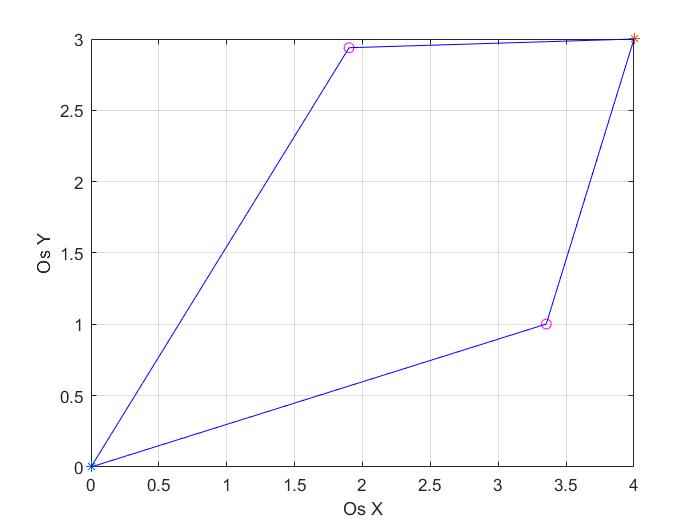


plot(psxa,psya,'o','Color','magenta'); text(psxa+3,psya-3,'Sa');
x=[0 psxa];
y=[0 psya];
line(x,y,'Color','blue');

x=[psxa px];
y=[psya py];
line(x,y,'Color','blue');

plot(psxb,psyb,'o','Color','magenta'); text(psxb+3,psyb-3,'Sa');
x=[0 psxb];
y=[0 psyb];
line(x,y,'Color','blue');

x=[psxb px];
y=[psyb py];
line(x,y,'Color','blue');



%A rješenje
theta1a

theta1a = 16.6355

theta2a

theta2a = 55.4346


q1=theta1a*pi/180

q1 = 0.2903

q2=theta2a*pi/180

q2 = 0.9675


J=double(subs(J))

J =    -3.0000   -1.9980
    4.0000    0.6465


subs(JT)

$$ans = \left(\begin{array}{cc} -\frac{7\,\sin\left(\frac{5230385377690007}{18014398509481984}\right)}{2}-\frac{21\,\sin\left(\frac{22659601155180879}{18014398509481984}\right)}{10} & \frac{7\,\cos\left(\frac{5230385377690007}{18014398509481984}\right)}{2}+\frac{21\,\cos\left(\frac{22659601155180879}{18014398509481984}\right)}{10}\\ -\frac{21\,\sin\left(\frac{22659601155180879}{18014398509481984}\right)}{10} & \frac{21\,\cos\left(\frac{22659601155180879}{18014398509481984}\right)}{10} \end{array}\right)$$

JT=double(subs(JT))

JT =    -3.0000    4.0000
   -1.9980    0.6465



M=double(subs(JT*F))

M =  -299.0381
 -703.5413



%B rješenje
%theta1b
%theta2b

%q1=theta1b*pi/180
%q2=theta2b*pi/180

%J=double(subs(J))
%subs(JT)
%JT=double(subs(JT))

%M=double(subs(JT*F))